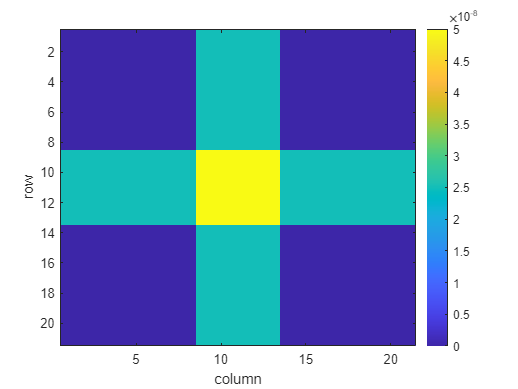

test_object{1} = imread('test_object.tif');
tumor_coords = rowcol_pairs(test_object);
rad_map = radiation_beam(tumor_coords(1).rows,tumor_coords(1).cols,0.5e-8,test_object{1});
figure;
imagesc(rad_map);
xlabel("column")
ylabel("row")
colorbar;

function rad_map = radiation_beam(rows,cols,intensity,mri_image)
    % Initialize the radiation map with zeros
    rad_map = zeros(size(mri_image)); % everything else should be 0
    intensity=intensity*5; % scale the color bar
    rad_map(rows, :) = rad_map(rows,:)+intensity; % the row of the single beam
    rad_map(:,cols)=rad_map(:,cols)+intensity; % the column of the single beam
end

function tumor_coords = rowcol_pairs(patient_data)
[rows,cols]=find(patient_data{:}>250);
tumor_coords = struct("rows", rows, "cols", cols);
end
